# Cereal Nutrition - Exploring

## 1.

Load `cereal_ex.mat`.  This file contains a table of nutritional data for 65 breakfast cereals.  The row names are the names of the cereals.  The variables are: a code representing the manufacturer, whether it is a hot or cold cereal, serving size information (weight and volume of a single serving), and nutritional information (calories, fat, fiber, protein, sodium, etc.).

load cereal_ex
cereal

cereal = 65×13 table
                                 Manufacturer    Type    Calories    Cups    Weight    Protein    Fat    Sodium    Fiber    Carbohydrates    Sugars    Potassium    Vitamins
                                 ____________    ____    ________    ____    ______    _______    ___    ______    _____    _____________    ______    _________    ________
    100% Bran                         N          Cold       70       0.33        1        4        1      130        10            5            6         280          25   
 

## 2.

Create two histograms of the cereal calorie content: one of the calorie content *per serving *and another with the calorie content *per cup* of cereal.

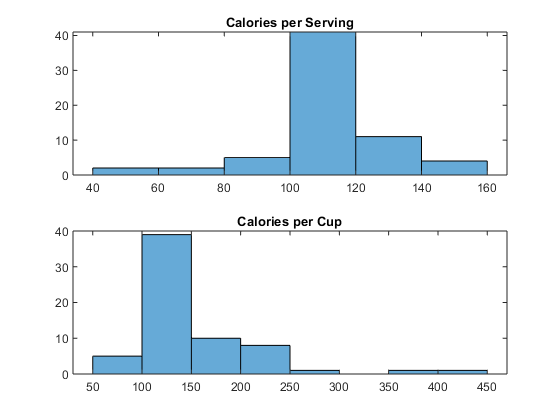

figure
subplot(2,1,1)
histogram(cereal.Calories)
title('Calories per Serving')

subplot(2,1,2)
histogram(cereal.Calories./cereal.Cups)
title('Calories per Cup')

## 3.

Find the median and mean values of the calorie data per serving and per cup.

CalPerServing = [median(cereal.Calories);mean(cereal.Calories)];
CalPerCup = [median(cereal.Calories./cereal.Cups);mean(cereal.Calories./cereal.Cups)];
% display as a table
cal = table(CalPerServing,CalPerCup,'RowNames',{'Median Value','Average Value'})

cal = 2×2 table
                     CalPerServing    CalPerCup
                     _____________    _________
    Median Value           110         134.33  
    Average Value       107.38         149.41  

## 4.

Determine how many standard deviations away from the average value the maximum value for calories per serving is.

cerealStd = std(cereal.Calories);
cerealMax = max(cereal.Calories);
cerealAve = mean(cereal.Calories);
fromMean = (cerealMax-cerealAve)/cerealStd;

disp(['The max calorie value is ',num2str(fromMean),...
    ' standard deviations from the mean']);

The max calorie value is 2.9576 standard deviations from the mean


## 5.

Calculate the correlation matrix. Use the `imagesc` function to visualize the correlations. Which variables are most highly correlated? Create a scatter plot of these two variables.

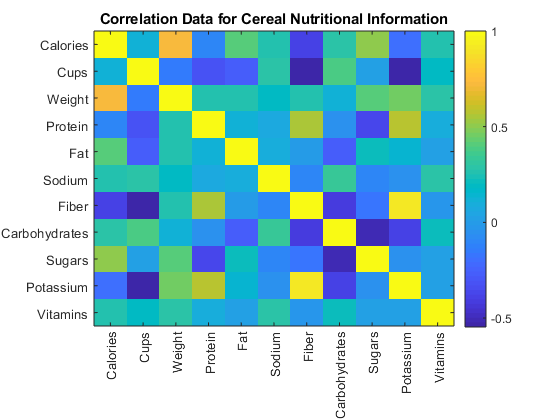

cerealCorr = corr(cereal{:,3:end});
%  Plot
imagesc(cerealCorr)
colorbar
title('Correlation Data for Cereal Nutritional Information')
%  Get labels
axesLabels = cereal.Properties.VariableNames(3:end);
%  Change axis labels
xticks(1:size(cerealCorr,2))
yticks(1:size(cerealCorr,1))
xticklabels(axesLabels)
yticklabels(axesLabels)
xtickangle(90)

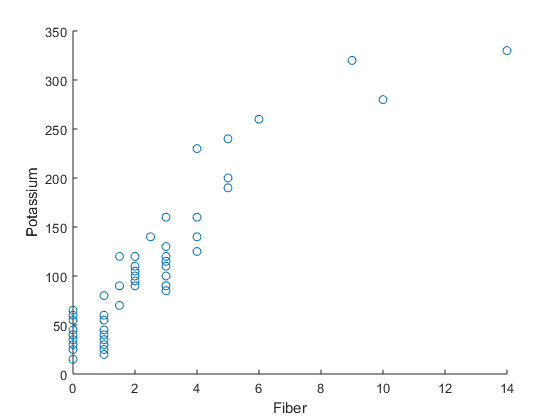


figure
scatter(cereal.Fiber,cereal.Potassium)
xlabel('Fiber')
ylabel('Potassium')


disp(['The correlation between fiber and potassium is ',...
         num2str(corr(cereal.Fiber,cereal.Potassium))])

The correlation between fiber and potassium is 0.92685


## 6. 

Create a boxplot of fiber, grouped by manufacturer. Which manufacturers appear to specialize in high-fiber cereals?

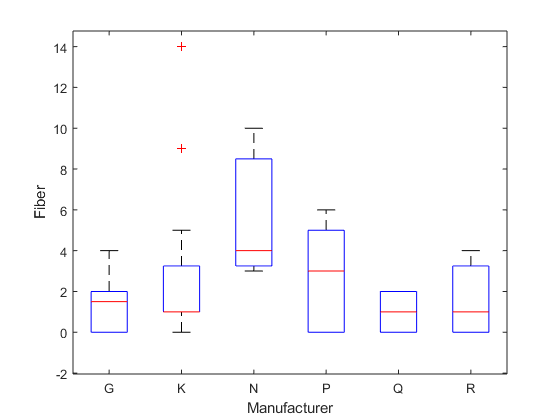

boxplot(cereal.Fiber,cereal.Manufacturer)
ylabel('Fiber')
xlabel('Manufacturer')

Manufacturer "N" (Nabisco) appears to make high-fiber cereals. "P" (Post) might be a bit higher than the others, but the range is quite large, so it's hard to know for sure.